clear 
clc

## Parameters Pre-setting

V0 = 0.895;                     % input swing
C1 = 38.72E-12;                 % load cap
Fs = 10E6;                      % sample rate
wt = primes(512)                % generate prime number

wt =      2     3     5     7    11    13    17    19    23    29    31    37    41    43    47    53    59    61    67    71    73    79    83    89    97   101   103   107   109   113   127   131   137   139   149   151   157   163   167   173   179   181   191   193   197   199   211   223   227   229


Fin = Fs * wt / 1024            % input frequency (Hz)

Fin = 1.0e+06 *

    0.0195    0.0293    0.0488    0.0684    0.1074    0.1270    0.1660    0.1855    0.2246    0.2832    0.3027    0.3613    0.4004    0.4199    0.4590    0.5176    0.5762    0.5957    0.6543    0.6934    0.7129    0.7715    0.8105    0.8691    0.9473    0.9863    1.0059    1.0449    1.0645    1.1035    1.2402    1.2793    1.3379    1.3574    1.4551    1.4746    1.5332    1.5918    1.6309    1.6895    1.7480    1.7676    1.8652    1.8848    1.9238    1.9434    2.0605    2.1777    2.2168    2.2363


Ron0 = 6.5*4;                  % for m*(W/L) = 16*3u/200n
NUM_FRE = length(wt);           % number of frequency
NUM_SAM = 1024;                 % number of sample point

## Reading simulation waveform

CSVFILE = 'SD_Exchange_Voutd_Sampled_m8.csv';
opts = detectImportOptions(CSVFILE);
preview(CSVFILE, opts)

ans = 8×194 table
    Vout_sampled_fin_19531_25_X    Vout_sampled_fin_19531_25_Y    Vout_sampled_fin_29296_88_X    Vout_sampled_fin_29296_88_Y    Vout_sampled_fin_48828_12_X    Vout_sampled_fin_48828_12_Y    Vout_sampled_fin_68359_38_X    Vout_sampled_fin_68359_38_Y    Vout_sampled_fin_107421_9_X    Vout_sampled_fin_107421_9_Y    Vout_sampled_fin_126953_1_X    Vout_sampled_fin_126953_1_Y    Vout_sampled_fin_166015_6_X    Vout_sampled_fin_166015_6_Y    Vout_sampled_fin_185546_9_X    Vout_sampled_fin_185546_9_Y    Vout_sampled_fin_224609_4_X    Vout_sampled_fin_224609_4_Y    Vout_sampled_fin_283203_1_X    Vout_sampled_fin_283203_1_Y    Vout_sampl

opts.SelectedVariableNames = 2 : 2 : NUM_FRE*2;
M = readmatrix(CSVFILE, opts);
M(end,:) = [];

## Check the read data

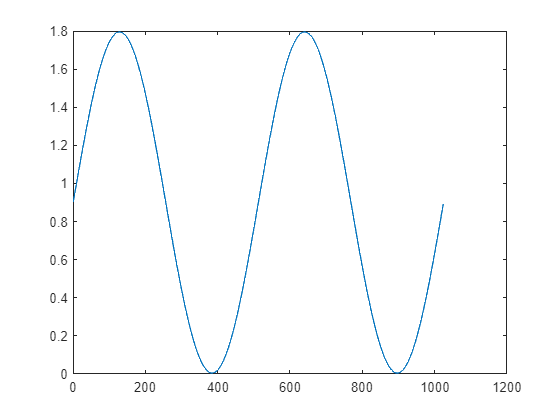

plot(M(:, 1))

[r, harmpow, harmfre] = thd(repmat(M(:,end),16,1 ), Fs, 5, 'aliased')

r = -73.7347

harmpow =    -3.9783
  -82.4864
  -79.5516
 -118.1241
  -96.9592


harmfre = 1.0e+06 *

    4.9707
    0.0586
    4.9121
    0.1172
    4.8535


## Get THD from the signal

HD3_simulation_8 = zeros(1, NUM_FRE);
for i = 1:NUM_FRE
    [~, harmpow, ~] = thd(repmat(M(:,i), 4, 1), Fs, 5, 'aliased');
    HD3_simulation_8(i) = harmpow(3) - harmpow(1);
end

HD_temp = getHD_new(Ron0, V0, C1, Fin, -1.15);
HD3_calculation_m8 = reshape(HD_temp(1,2,:), 1, NUM_FRE);
HD_temp = getHD_new(Ron0/2, V0, C1, Fin, -1.15);
HD3_calculation_m16 = reshape(HD_temp(1,2,:), 1, NUM_FRE);


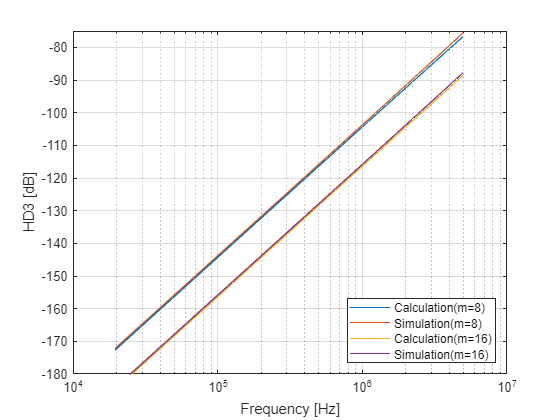

load('HD3_simulation_m16.mat');
figure
semilogx(Fin, HD3_calculation_m8);     % need to be calibration
hold on;
semilogx(Fin, HD3_simulation_8);
semilogx(Fin, HD3_calculation_m16);
semilogx(Fin, HD3_simulation_16);
ylim([-180, -75])
grid on;
box on;
xlabel("Frequency [Hz]");
ylabel("HD3 [dB]");
legend({'Calculation(m=8)', 'Simulation(m=8)', ...
    'Calculation(m=16)', 'Simulation(m=16)'}, "Location", "southeast")

## generate Index

L = length(Fin);
index = [];
index(1) = 1;
j = 2;
i = 1;
while i <= 97
    i = (index(j - 1) + j);
    index(j) = index(j - 1) + (j-1); 
    
    j = j+1;
end
index(end) = 97

index =      1     2     4     7    11    16    22    29    37    46    56    67    79    92    97


## 美化绘图

由于计算式与仿真结果太接近了，因此要在绘制图像的时候需要对Calculation的点加上Tag，但是过密的数据点不利于Tag的绘制

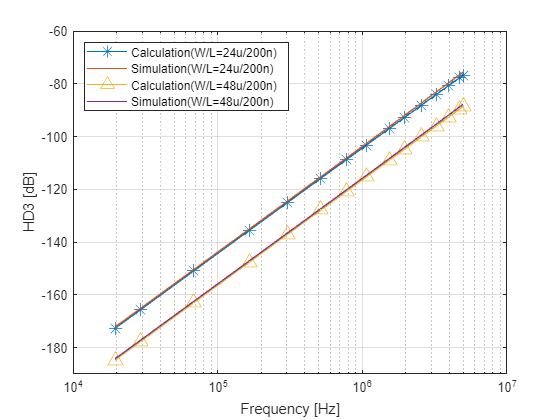


load('HD3_simulation_m16.mat');

% index = [1:10, 11:2:20, 21:3:30, 31:4:40, 41:5:50, 51:6:60, 61:7:70, 71:8:80, 81:9:90, 91:10:97];
figure
semilogx(Fin(index), HD3_calculation_m8(index), '-*', 'MarkerSize', 10);     % need to be calibration
hold on;
semilogx(Fin(index), HD3_simulation_8(index));
semilogx(Fin(index), HD3_calculation_m16(index), '-^', 'MarkerSize',10);
semilogx(Fin(index), HD3_simulation_16(index));
ylim([-190, -60])
% xlim([1E4, 5E7])
grid on;
box on;
xlabel("Frequency [Hz]");
ylabel("HD3 [dB]");
legend({'Calculation(W/L=24u/200n)', 'Simulation(W/L=24u/200n)', ...
    'Calculation(W/L=48u/200n)', 'Simulation(W/L=48u/200n)'}, "Location", "northwest")

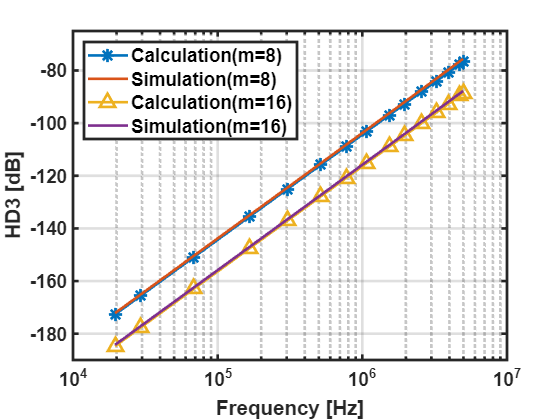


figure()
createfigure_Paper_DataProcess_1(Fin(index), [HD3_calculation_m8(index); ...
    HD3_simulation_8(index);HD3_calculation_m16(index); HD3_simulation_16(index)])

## Vds(t)

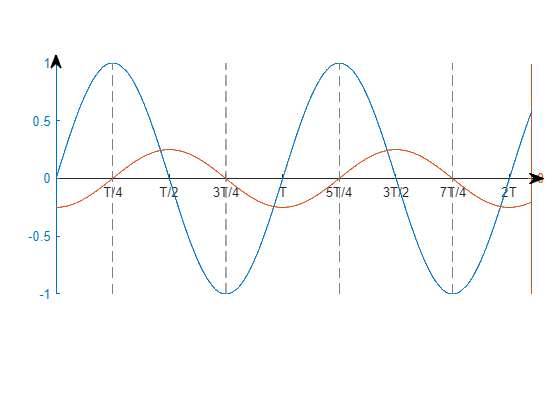

dt = 1 / 1024;
t = 0:dt:3-dt;

vds = -0.3*cos(2*pi*t);
vin = sin(2*pi*t);

% vds_m = repmat(vds, [1, 2]);

figure
yyaxis left
p = plot(t, vin);

yyaxis right 
plot(t, vds)
xmax = 2.1;
xlim([0, xmax]);
ylim([-1.2, 1.2]);


% 窄边框绘图参数设置

x0_1=0.1;    % 轴框起始点横坐标

y0_1=0.3;    % 轴框起始点纵坐标

width=0.85;  % 轴框宽度

height=0.55; % 轴框高度

% 轴框位置

pos=[x0_1,y0_1,width,height];

set(gca,'Position',pos);box off

% 轴框线条属性

% set(gca,'LineWidth',1.5, 'FontName','Times','FontSize',15)

%轴箭头始终位置与标注

xaPos=x0_1+width;xbPos=xaPos+0.02;

annotation('arrow',[xaPos,xbPos],[y0_1+height/2,y0_1+height/2],'headStyle','vback2')

% y轴箭头始终位置与标注

yaPos=y0_1+height;ybPos=yaPos+0.02;

annotation('arrow',[x0_1,x0_1],[yaPos,ybPos],'headStyle','vback2')

for i=1:2:floor(xmax)*4
    annotation('line', [x0_1+width*(1/xmax)*i/4, x0_1+width*(1/xmax)*i/4], [y0_1, yaPos], ...
        'LineStyle','--', 'Color', [0.5,0.5,0.5])
end
% annotation('line', [x0+width*(1/xmax)/4, x0+width*(1/xmax)/4], [y0, yaPos], ...
%     'LineWidth',1.5, 'LineStyle','--', 'Color', [0.5,0.5,0.5])
% annotation('line', [x0+width*(1/xmax)*3/4, x0+width*(1/xmax)*3/4], [y0, yaPos], ...
%     'LineWidth',1.5, 'LineStyle','--', 'Color', [0.5,0.5,0.5])

set(gca, 'YTick', [ 0 ]);
% set(gca, 'YTickLabel', {'- V_0\omega_{in}', '0', 'V_0\omega_{in}'})
set(gca, 'XTick', [0 0.25 0.5 0.75 1 1.25, 1.5 1.75 2])
set(gca, 'XTicklabel', {'0', 'T/4', 'T/2', '3T/4', 'T', '5T/4', '3T/2', '7T/4', '2T'});
set(gca,'XAxisLocation','origin')

## Ron(t)

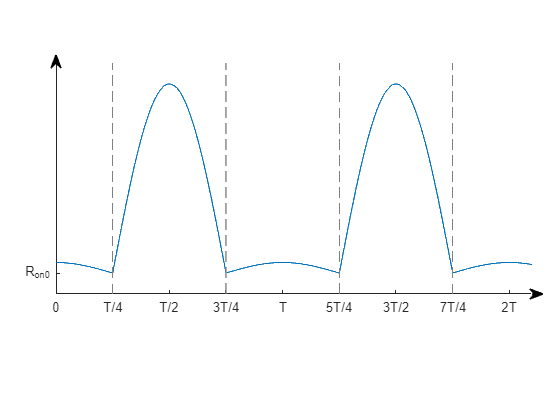

ron = zeros(1, 1024);
ron_dc = 0.1;
seg_line = (1024)/4;
ron(1 : seg_line) = ron_dc + 0.05*cos(2*pi*t(1 : seg_line));
ron(seg_line+1 : seg_line*3) = ron_dc - 0.9*cos(2*pi*t(seg_line+1 : seg_line*3));
ron(seg_line*3+1 : seg_line*4) = ron_dc + 0.05*cos(2*pi*t(seg_line*3+1 : seg_line*4));
figure
ron = repmat(ron, 1, floor(length(t)/1024));
plot(t,ron)
ronxmax = 2.1;
ronymax = 1.1;
xlim([0, ronxmax])
ylim([0, ronymax])
% 窄边框绘图参数设置

x0_1=0.1;    % 轴框起始点横坐标

y0_1=0.3;    % 轴框起始点纵坐标

width=0.85;  % 轴框宽度

height=0.55; % 轴框高度

% 轴框位置

pos=[x0_1,y0_1,width,height];

set(gca,'Position',pos);box off

% 轴框线条属性
% 
% set(gca,'LineWidth',1.5, 'FontName','Times','FontSize',15)

% x轴箭头始终位置与标注

xaPos=x0_1+width;xbPos=xaPos+0.02;

annotation('arrow',[xaPos,xbPos],[y0_1,y0_1],'headStyle','vback2')

% y轴箭头始终位置与标注

yaPos=y0_1+height;ybPos=yaPos+0.02;

annotation('arrow',[x0_1,x0_1],[yaPos,ybPos],'headStyle','vback2')

for i=1:2:floor(xmax)*4
    annotation('line', [x0_1+width*(1/xmax)*i/4, x0_1+width*(1/xmax)*i/4], [y0_1, yaPos], ...
        'LineStyle','--', 'Color', [0.5,0.5,0.5])
end
% annotation('line', [x0, xaPos], [y0+height*(1/ronymax)*0.1, y0+height*(1/ronymax)*0.1], ...
%     'LineWidth',1.5, 'LineStyle','--', 'Color', [0.5,0.5,0.5])


set(gca, 'YTick', [0.1]);
set(gca, 'YTickLabel', {'R_{on0}'})
set(gca, 'XTick', [0 0.25 0.5 0.75 1 1.25, 1.5 1.75 2])
set(gca, 'XTicklabel', {'0', 'T/4', 'T/2', '3T/4', 'T', '5T/4', '3T/2', '7T/4', '2T'});
set(gca,'XAxisLocation','origin')

## All in one figure

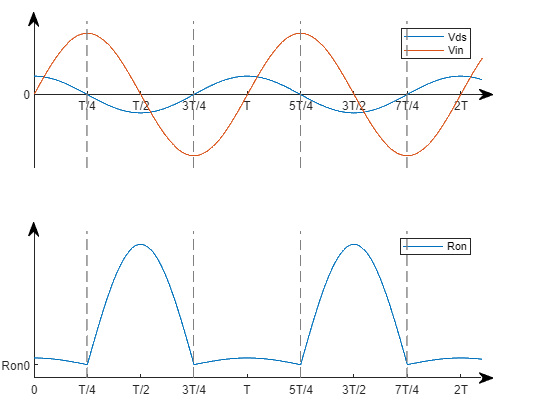

% Generate Waveform 
Num_sample = 1024;
dt = 1 / Num_sample;

t = 0:dt:3-dt;

vds = 0.3*cos(2*pi*t);
vin = sin(2*pi*t);

ron = zeros(1, Num_sample);
ron_dc = 0.1;
seg_line = (Num_sample)/4;
ron(1 : seg_line) = ron_dc + 0.05*cos(2*pi*t(1 : seg_line));
ron(seg_line+1 : seg_line*3) = ron_dc - 0.9*cos(2*pi*t(seg_line+1 : seg_line*3));
ron(seg_line*3+1 : seg_line*4) = ron_dc + 0.05*cos(2*pi*t(seg_line*3+1 : seg_line*4));
figure
ron = repmat(ron, 1, floor(length(t)/Num_sample));

figure
% Vin and Vds
subplot(2,1,1)
p = plot(t, vds, t, vin);
xmax = 2.1;
xlim([0, xmax]);
ylim([-1.2, 1.2]);

legend(['Vds'; 'Vin'] , 'Location', 'northeast')

% 窄边框绘图参数设置

x0_1=0.06;    % 轴框起始点横坐标

y0_1=0.6;    % 轴框起始点纵坐标

width=0.8;  % 轴框宽度

height=0.35; % 轴框高度

% 轴框位置

pos=[x0_1,y0_1,width,height];

set(gca,'Position',pos);box off

% 轴框线条属性

% set(gca,'LineWidth',1.5, 'FontName','Times','FontSize',15)

%轴箭头始终位置与标注

xaPos=x0_1+width;xbPos=xaPos+0.02;

annotation('arrow',[xaPos,xbPos],[y0_1+height/2,y0_1+height/2],'headStyle','vback2')

% y轴箭头始终位置与标注

yaPos=y0_1+height;ybPos=yaPos+0.02;

annotation('arrow',[x0_1,x0_1],[yaPos,ybPos],'headStyle','vback2')

for i=1:2:floor(xmax)*4
    annotation('line', [x0_1+width*(1/xmax)*i/4, x0_1+width*(1/xmax)*i/4], [y0_1, yaPos], ...
        'LineStyle','--', 'Color', [0.5,0.5,0.5])
end
% annotation('line', [x0+width*(1/xmax)/4, x0+width*(1/xmax)/4], [y0, yaPos], ...
%     'LineWidth',1.5, 'LineStyle','--', 'Color', [0.5,0.5,0.5])
% annotation('line', [x0+width*(1/xmax)*3/4, x0+width*(1/xmax)*3/4], [y0, yaPos], ...
%     'LineWidth',1.5, 'LineStyle','--', 'Color', [0.5,0.5,0.5])

set(gca, 'YTick', [ 0 ]);
% set(gca, 'YTickLabel', {'- V_0\omega_{in}', '0', 'V_0\omega_{in}'})
set(gca, 'XTick', [0 0.25 0.5 0.75 1 1.25, 1.5 1.75 2])
set(gca, 'XTicklabel', {'0', 'T/4', 'T/2', '3T/4', 'T', '5T/4', '3T/2', '7T/4', '2T'});
set(gca,'XAxisLocation','origin')

% Ron
subplot(2,1,2)
plot(t,ron)
ronxmax = 2.1;
ronymax = 1.1;
xlim([0, ronxmax])
ylim([0, ronymax])

legend(['Ron'] , 'Location', 'northeast')

% 窄边框绘图参数设置

x0_2=0.06;    % 轴框起始点横坐标

y0_2=0.1;    % 轴框起始点纵坐标


% 轴框位置

pos=[x0_2,y0_2,width,height];

set(gca,'Position',pos);box off

% 轴框线条属性
% 
% set(gca,'LineWidth',1.5, 'FontName','Times','FontSize',15)

% x轴箭头始终位置与标注

xaPos=x0_2+width;xbPos=xaPos+0.02;

annotation('arrow',[xaPos,xbPos],[y0_2,y0_2],'headStyle','vback2')

% y轴箭头始终位置与标注

yaPos=y0_2+height;ybPos=yaPos+0.02;

annotation('arrow',[x0_2,x0_2],[yaPos,ybPos],'headStyle','vback2')

for i=1:2:floor(xmax)*4
    annotation('line', [x0_2+width*(1/xmax)*i/4, x0_2+width*(1/xmax)*i/4], [y0_2, yaPos], ...
        'LineStyle','--', 'Color', [0.5,0.5,0.5])
end
% annotation('line', [x0, xaPos], [y0+height*(1/ronymax)*0.1, y0+height*(1/ronymax)*0.1], ...
%     'LineWidth',1.5, 'LineStyle','--', 'Color', [0.5,0.5,0.5])

set(gca, 'YTick', [0.1]);
set(gca, 'YTickLabel', {'Ron0'})
set(gca, 'XTick', [0 0.25 0.5 0.75 1 1.25, 1.5 1.75 2])
set(gca, 'XTicklabel', {'0', 'T/4', 'T/2', '3T/4', 'T', '5T/4', '3T/2', '7T/4', '2T'});
set(gca,'XAxisLocation','origin')